# Example

Here are some experimental wind tunnel data for Force *(F)*versus velocity *(v)* :

These data can also be described by the following function:


$$F=0\ldotp 2741\;{\textrm{𝑣}}^{1\ldotp 9842}$$


First, generate experimental measured force versus velocity. Then, plot the function *F* for v from 0 to 100 m/s.

## Solution

clear, clc
v = 10:10:80

v =     10    20    30    40    50    60    70    80


F = [25 70 380 550 610 1220 830 1450]

F =           25          70         380         550         610        1220         830        1450



F_calc = ones(1,length(v));
% F_calc = @(v) 0.2741*v^1.9842;
% F_calc_2 = 0.2741*v.^1.9842
for i=1:length(F_calc)
    F_calc(i) = wind(v(i));
end
disp(F_calc)

   1.0e+03 *

    0.0264    0.1046    0.2338    0.4137    0.6442    0.9249    1.2559    1.6369



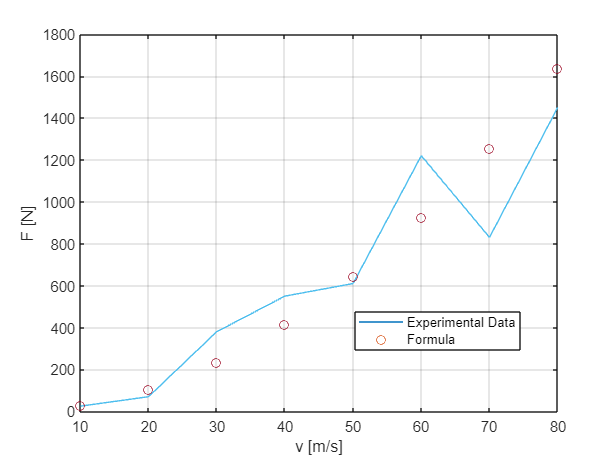

% Visualization
plot(v,F)
hold on 
plot(v,F_calc,'o')
grid on
xlabel('v [m/s]')
ylabel('F [N]')
legend('Experimental Data','Formula','Location','best')